syms u(t) v(t)

f = @(t,u,v) v;
g = @(t,u,v) -sin(u) - 0.3 * v;

a = 0;
b = 15;
n = 100;
u0 = pi/2;
v0 = 0;

%[t,u,v] = MEuler_SED(f,g,a,b,n,u0,v0);
[t,u,v] = NRK2_SED(f,g,a,b,n,u0,v0);

array2table([t.',u.',v.'], "VariableNames",{'t', 'u', 'v'})

ans = 101×3 table
     t          u           v    
    ____    _________    ________

       0       1.5708           0
    0.15       1.5595    -0.14663
     0.3       1.5268    -0.28675
    0.45       1.4735    -0.42041
     0.6       1.4007    -0.54724
    0.75       1.3093    -0.66639
     0.9       1.2008    -0.77642
    1.05       1.0764    -0.87535
     1.2      0.93819    -0.96068
    1.35      0.78825     -1.0297
     1.5       0.6293     -1.0796
    1.65      0.46438     -1.1081
     1.8      0.29687     -1.1134
    1.95      0.13033     -1.0951
     2.1    -0.031706     -1.0537
    2.25     -0.18585    -0.99094


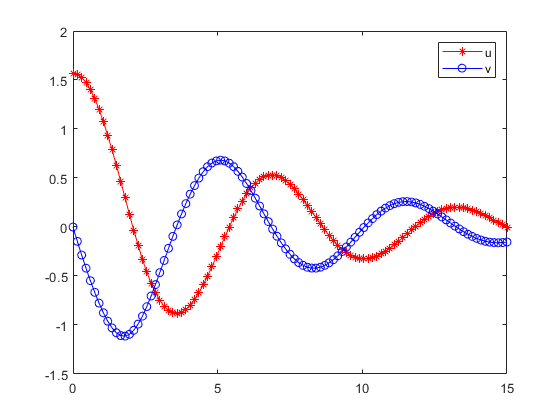


plot(t, u, "-r*");
hold on;
plot(t, v, "-bo");
hold off;
legend("u","v")